1.用于trail水平的极值筛选

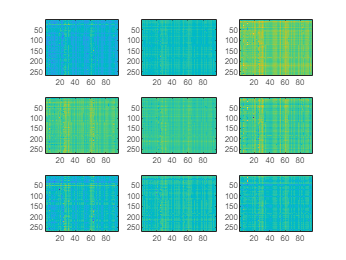

oridata1 = squeeze(mean(all_orient_data(:,420:1440,:,:),2));
oridata2 = squeeze(mean(all_orient_data,2));
figure(2);
for i =1:9
    subplot(3,3,i);
    imagesc(1:96,1:270,oridata1(:,:,i));
end

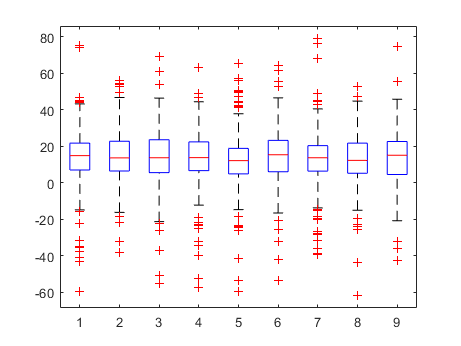

%上面看了一下感觉还是需要做通道平均
ori_c1 = squeeze(mean(oridata1,2));
ori_c2 = squeeze(mean(oridata2,2));
figure;
boxplot(ori_c1)

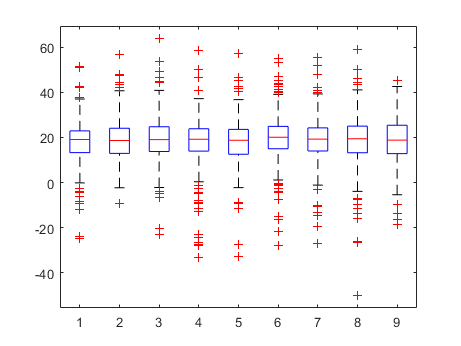

figure;
boxplot(ori_c2)

%四分位的计算
Q3 = quantile(ori_c2(:,1),0.75);  %第三四分位
Q1 = quantile(ori_c2(:,1),0.25);  %第一四分位
U = Q3 +1.5*(Q3-Q1);              %上限
L = Q1 -1.5*(Q3-Q1);              %下限

%除去异常的idx
idx = {};
for ori = 1:9
    idx{ori} = find(ori_c2(:,ori)<U & ori_c2(:,ori)>L);
end